# (単純化した)バレーボールのシミュレーション

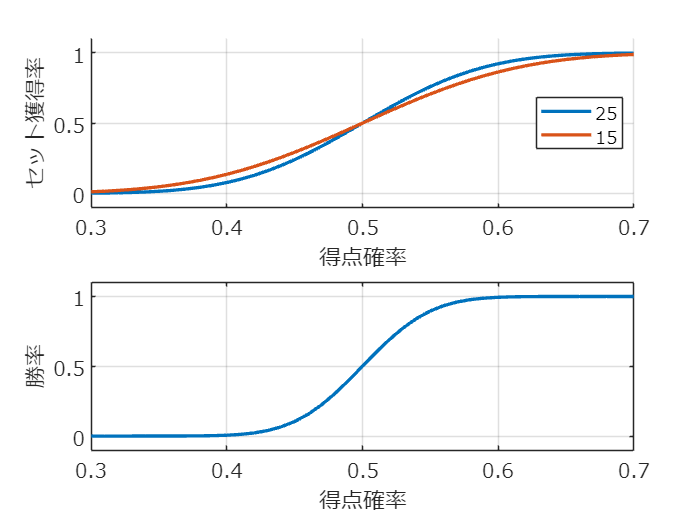

clear;
clc;
close all;

figure;
tiledlayout(2,1);
nexttile;
hold on;

for wonScore=[25,15]    %1セット獲得するために必要な点数

    pVals=(0:0.01:1)';   %得点確率
    pSetWin=[]; %セット獲得率
    for pVal=pVals'
        pMat=zeros(wonScore+1); %両チームの得点の確率を保存する行列
        pMat(1,1)=1;
        for totalScore=0:2*wonScore-2
            for n1=1:totalScore+1
                n2=totalScore-n1+2;
                if (n1>=1) && (n1<=wonScore) ...
                        && (n2>=1) && (n2<=wonScore)
                    pMat(n1+1,n2)=pMat(n1+1,n2)+pMat(n1,n2)*pVal;
                    pMat(n1,n2+1)=pMat(n1,n2+1)+pMat(n1,n2)*(1-pVal);

                end
            end
        end
        pSetWin=[pSetWin;sum(pMat(end,:))];
    end

    plot(pVals,pSetWin,'LineWidth',2);
    switch wonScore
        case 25
            pSetWin25=pSetWin;
        case 15
            pSetWin15=pSetWin;
    end
end
grid on;
ylim([-0.1 1.1]);xlim([0.3 0.7]);
set(gca,'fontname','メイリオ','fontsize',12);
xlabel('得点確率');
ylabel('セット獲得率');
legend({'25','15'},'Location','best');
nexttile
pMatchWin ...
    =pSetWin25.^3 ...
    +3*pSetWin25.^3 .*(1-pSetWin25) ...
    +6*pSetWin25.^2 .*(1-pSetWin25).^2 .* pSetWin15;
plot(pVals,pMatchWin,'LineWidth',2);
grid on;
ylim([-0.1 1.1]);xlim([0.3 0.7]);
set(gca,'fontname','メイリオ','fontsize',12);
xlabel('得点確率');
ylabel('勝率');

exportgraphics(gcf,'fig_simpleVolleyball.pdf')